clc; clear all; close all;

#### Generating Random Data to Transmit

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16; 
N_XData = 84;
Bits_per_set=64;
size_training_data = Bits_per_set*N_Training;
size_X = Bits_per_set*N_XData; %Size of data - 84 sets of 64 bits

range = [-1 1]; %List of wanted values
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

Create Data and Training Data

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

#### IDFT - Takes inverse discrete fourier tranform of data

Add Cyclic Prefix after each ifft

%IFFT of each individual set of 64
%Add prefix 
Len_CP = 16;
n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data
tx_data = zeros(8000,1);

for x_time = 1:1:n_data
    Data_x_n = message(1 + 64*(x_time-1):x_time*64);
    Data_X_n = ifft(Data_x_n);
    cyclic_prefix = Data_X_n(49:end);
    Prefix_w_data = [cyclic_prefix ; Data_X_n];
    tx_data(1+80*(x_time-1):80*(x_time)) = Prefix_w_data;
end

#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel((tx_data));

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index); %Should be 9

%Remove Extra Data
rx_data = rx_data(shift1_train:shift1_train+length(tx_data)-1); %Should be 8000 bits

Estimate Channel: Estimating channel for each set of 64 bits using the Training Data

H = zeros(64,1);

%Obtain Training Data
Size_PC = 16;
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_set; %1280 Bits
Training_data_xm= rx_data(1:Size_Training_PC)

Training_data_xm =    0.0007 - 0.0026i
   0.0017 + 0.0298i
   0.1196 - 0.1907i
   0.0611 + 0.0443i
  -0.0431 + 0.1055i
   0.1366 - 0.1111i
  -0.0901 + 0.0490i
  -0.1192 + 0.0017i
  -0.0045 + 0.1169i
  -0.0316 + 0.0229i



Cleaned_Training_Data = zeros(N_Training*Bits_per_set,1);

%removing cyclic prefix
for V = 1:1:N_Training
    Set = Training_data_xm(1 + 80*(V-1):80*V);
    remove_prefix = Set(17:end);
    Cleaned_Training_Data(1+64*(V-1):64*V) = remove_prefix;
end

for G = 1:1:64  
    Data_N = Cleaned_Training_Data(G:64:end);
    Channel_estimate = Data_N./message(G);
    H(G) = mean(Channel_estimate);
end

Decode

Y_m = zeros(length(message),1);

%Remove All Cyclic Prefix
for V = 1:1:n_data
    Set = rx_data(1 + 80*(V-1):80*V);
    remove_prefix = Set(17:end);
    X_est = fftshift(fft(remove_prefix));
    X_est=X_est./H;
    Y_m(1 + 64*(V-1):64*V) = X_est;
end

Plot X_est

Norm_ret = real(Y_m) ./ abs(real(Y_m))

Norm_ret =      1
    -1
     1
     1
    -1
     1
    -1
     1
    -1
    -1


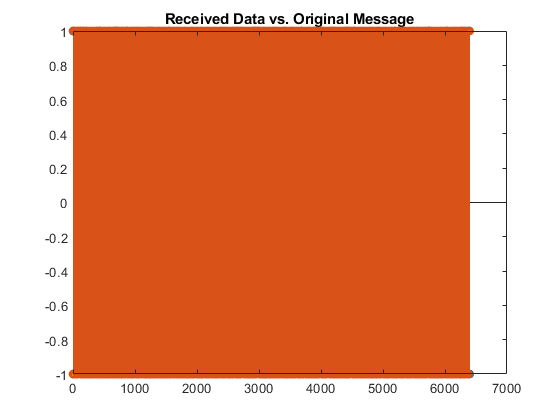


figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Error = abs(sum(diff)/(length(diff))) *100

Error = 50.2031

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end


Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);